# Control de estados LQI

clear

g = 9.81;
psi_d = deg2rad(0);
a = g*sin(psi_d);
b = g*cos(psi_d);
c = -g*cos(psi_d);
d = g*sin(psi_d);

m = 1.6;
Jn = [0.021915027 0.022124548 0.042349865];
Ts = 1/1000;

switch 8
    case 12
        A = [0 0 0 1 0 0 0 0 0 0 0 0;
             0 0 0 0 1 0 0 0 0 0 0 0;
             0 0 0 0 0 1 0 0 0 0 0 0;
             0 0 0 0 0 0 a b 0 0 0 0;
             0 0 0 0 0 0 c d 0 0 0 0;
             0 0 0 0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 0 0 0 1 0 0;
             0 0 0 0 0 0 0 0 0 0 1 0;
             0 0 0 0 0 0 0 0 0 0 0 1;
             zeros(3,12)];
        B = [zeros(5,4);
            1/m 0 0 0;
            zeros(3,4);
            0 1/Jn(1) 0 0;
            0 0 1/Jn(2) 0;
            0 0 0 1/Jn(3)];
        % C = [0 0 1 0 0 0 0 0 0 0 0 0;
        %      0 0 0 0 0 1 0 0 0 0 0 0;
        %      0 0 0 0 0 0 1 0 0 0 0 0;
        %      0 0 0 0 0 0 0 1 0 0 0 0;
        %      0 0 0 0 0 0 0 0 1 0 0 0;
        %      0 0 0 0 0 0 0 0 0 1 0 0;
        %      0 0 0 0 0 0 0 0 0 0 1 0;
        %      0 0 0 0 0 0 0 0 0 0 0 1];
        C = [0 0 1 0 0 0 0 0 0 0 0 0;
             0 0 0 0 0 0 1 0 0 0 0 0;
             0 0 0 0 0 0 0 1 0 0 0 0;
             0 0 0 0 0 0 0 0 1 0 0 0];
        D = zeros(size(C,1),4);
        sys = ss(A,B,C,D);
        
    case 8
        A = [0 1 zeros(1,6);
            zeros(1,8);
            zeros(3,5) eye(3);
            zeros(3,8)];
        B = [zeros(1,4);
            1/m 0 0 0;
            zeros(3,4);
            zeros(3,1) diag(1./Jn)];
        C = [1 0 0 0 0 0 0 0;
             0 0 1 0 0 0 0 0;
             0 0 0 1 0 0 0 0;
             0 0 0 0 1 0 0 0];
        D = zeros(size(C,1),4);
        sys = ss(A,B,C,D, 'StateName',{'z', 'Vz', 'phi', 'theta', 'psi', 'p', 'q', 'r'}, 'InputName', {'F', 'Tx', 'Ty', 'Tz'}, 'OutputName', {'z', 'phi', 'theta', 'psi'});
end
fprintf("Matriz de controlabilidad rango: %d", rank(ctrb(sys.A,sys.B)))

Matriz de controlabilidad rango: 8

fprintf("Matriz de Observabilidad rango: %d", rank(obsv(sys.A,sys.C)))

Matriz de Observabilidad rango: 8

dsys = c2d(sys, Ts,'zoh');

## LQI Continuo

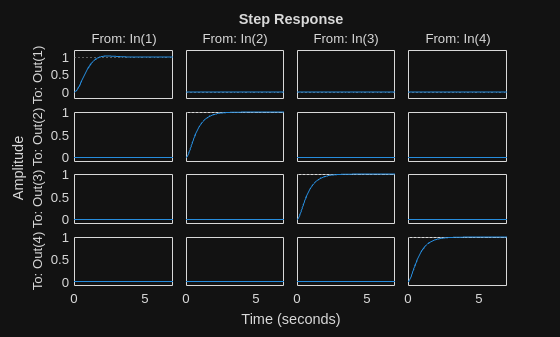

% lqi para modelo reducido a 8 estados
Q = diag([8 500 500 500 0.5 0.5 200 200 200 10 10 10]);
R = diag(0.0001*ones(1,4));
AA = [zeros(size(sys.C,1)+size(sys.A,1),size(sys.B,2)) [sys.C;sys.A]];
BB = [zeros(size(sys.B,2),size(sys.B,2));sys.B];
[K,~,P] = lqr(AA,BB,Q,R);
As = [sys.A-sys.B*K(:,5:end) sys.B*K(:,1:4); -sys.C zeros(4)];
Bs = [zeros(8,4); eye(4)];
Cs = [sys.C zeros(4)];
Ds = zeros(4);
sysc = ss(As,Bs,Cs,Ds);
step(sysc)

## Observador

Ke = place(sys.A',sys.C',5*P(5:end))';

## Ancho de banda

% sysc: tu modelo aumentado continuo (ss)
p = pole(sysc);
p_abs = abs(p(isfinite(p) & p~=0));
if isempty(p_abs)
    p_abs = [1e-2, 1e2]; % fallback
end

% rango basado en polos (margen)
wmin = max(1e-6, min(p_abs)*1e-3);
wmax = max(p_abs)*1e3;
w = logspace(log10(wmin), log10(wmax), 4000);

% singular values
S = sigma(sysc, w);             % r x r x nw
smax = squeeze(S(1,1,:));       % nw x 1

% referencia en bajas freq (promedio primeros N puntos)
N = min(30, numel(smax));
sv_ref = mean(smax(1:N));
thr = sv_ref * 10^(-3/20);      % -3 dB umbral

% buscar cruce -3 dB
idx = find(smax <= thr, 1, 'first');
if isempty(idx)
    % si no hay cruce, usar cruce relativo al pico
    [svPeak, idxPeak] = max(smax);
    thr2 = svPeak * 10^(-3/20);
    idx = find(smax <= thr2, 1, 'first');
    if isempty(idx)
        fprintf('No se alcanza -3 dB respecto a ref ni al pico en el rango w.\n');
        fc = NaN;
    else
        % interpolación en log(w)
        if idx>1
            x1 = log10(w(idx-1)); x2 = log10(w(idx));
            y1 = 20*log10(smax(idx-1)); y2 = 20*log10(smax(idx));
            thr_db = 20*log10(thr2);
            t = (thr_db - y1)/(y2 - y1);
            fc = 10^(x1 + t*(x2-x1));
        else
            fc = w(1);
        end
        fprintf('BW relativo al pico (-3 dB) ≈ %g rad/s\n', fc);
    end
else
    if idx>1
        x1 = log10(w(idx-1)); x2 = log10(w(idx));
        y1 = 20*log10(smax(idx-1)); y2 = 20*log10(smax(idx));
        thr_db = 20*log10(thr);
        t = (thr_db - y1)/(y2 - y1);
        fc = 10^(x1 + t*(x2-x1));
    else
        fc = w(1);
    end
    fprintf('Bandwidth (T, -3 dB respecto a baja freq) ≈ %g rad/s\n', fc);
end

No se alcanza -3 dB respecto a ref ni al pico en el rango w.



% recomendar frecuencia de muestreo
if ~isnan(fc) && fc>0
    fs_min = 10 * (fc/(2*pi));   % en Hz
    fs_reco = 20 * (fc/(2*pi));  % en Hz
    fprintf('Recomendación: fs ≥ %g Hz (mín), fs ≈ %g Hz (recomendado)\n', fs_min, fs_reco);
else
    fprintf('No se pudo estimar fc; inspecciona la curva de σ_max(ω).\n');
end

No se pudo estimar fc; inspecciona la curva de σ_max(ω).


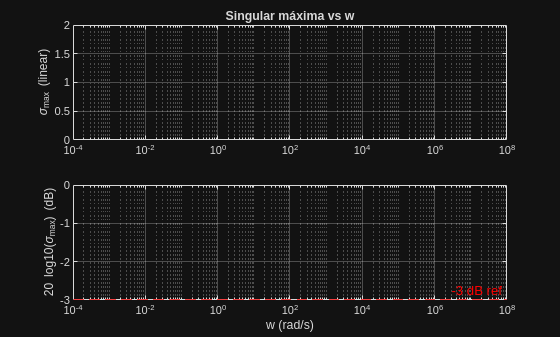


% plot para verificación
figure;
subplot(2,1,1); semilogx(w, smax,'b','LineWidth',1.2); grid on;
ylabel('\sigma_{max} (linear)'); title('Singular máxima vs w');
subplot(2,1,2); semilogx(w,20*log10(smax),'b','LineWidth',1.2); grid on; hold on;
if ~isnan(fc), xline(fc,'--k','BW'); end
yline(20*log10(thr),'--r','-3 dB ref');
xlabel('w (rad/s)'); ylabel('20 log10(\sigma_{max}) (dB)');

## LQI Discreto

Q = diag([1e6,1e6,1e6,1e6,8/(Ts^2),500/(Ts^2), 500/(Ts^2),500/(Ts^2),0.5/(Ts^2),0.5/(Ts^2),200/(Ts^2),200/(Ts^2)]);
R = diag([0.0001*Ts,0.0001*Ts,0.0001*Ts,0.0001*Ts]);
AA = [zeros(size(dsys.C,1)+size(dsys.A,1),size(dsys.B,2)) [dsys.C;dsys.A]];
BB = [zeros(size(dsys.B,2),size(dsys.B,2));dsys.B];
[K,~,P] = dlqr(AA,BB,Q,R);
As = [dsys.A-dsys.B*K(:,5:end) dsys.B*K(:,1:4); -dsys.C zeros(4)];
Bs = [zeros(8,4); eye(4)];
Cs = [dsys.C zeros(4)];
Ds = zeros(4);
step(As,Bs,Cs,Ds)
% Ke = place(sys.A',sys.C',5*P(5:end))'